# segmentaionUsingSkeletonAndImerode

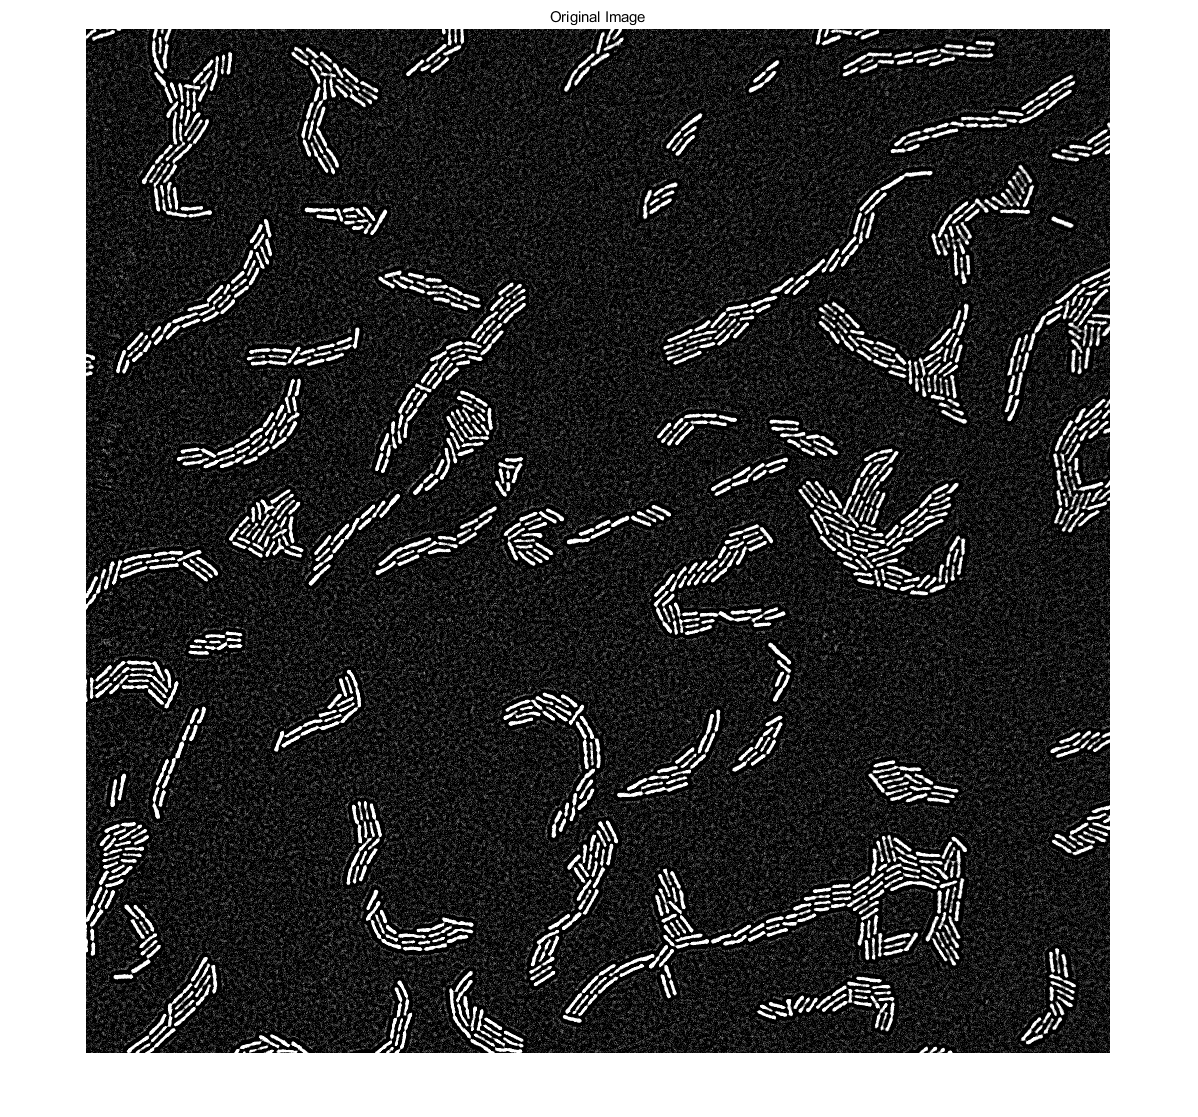

image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');
I=image;
se = strel('disk',2);
Io = imopen(I,se);
imshow(I), title('Original Image')

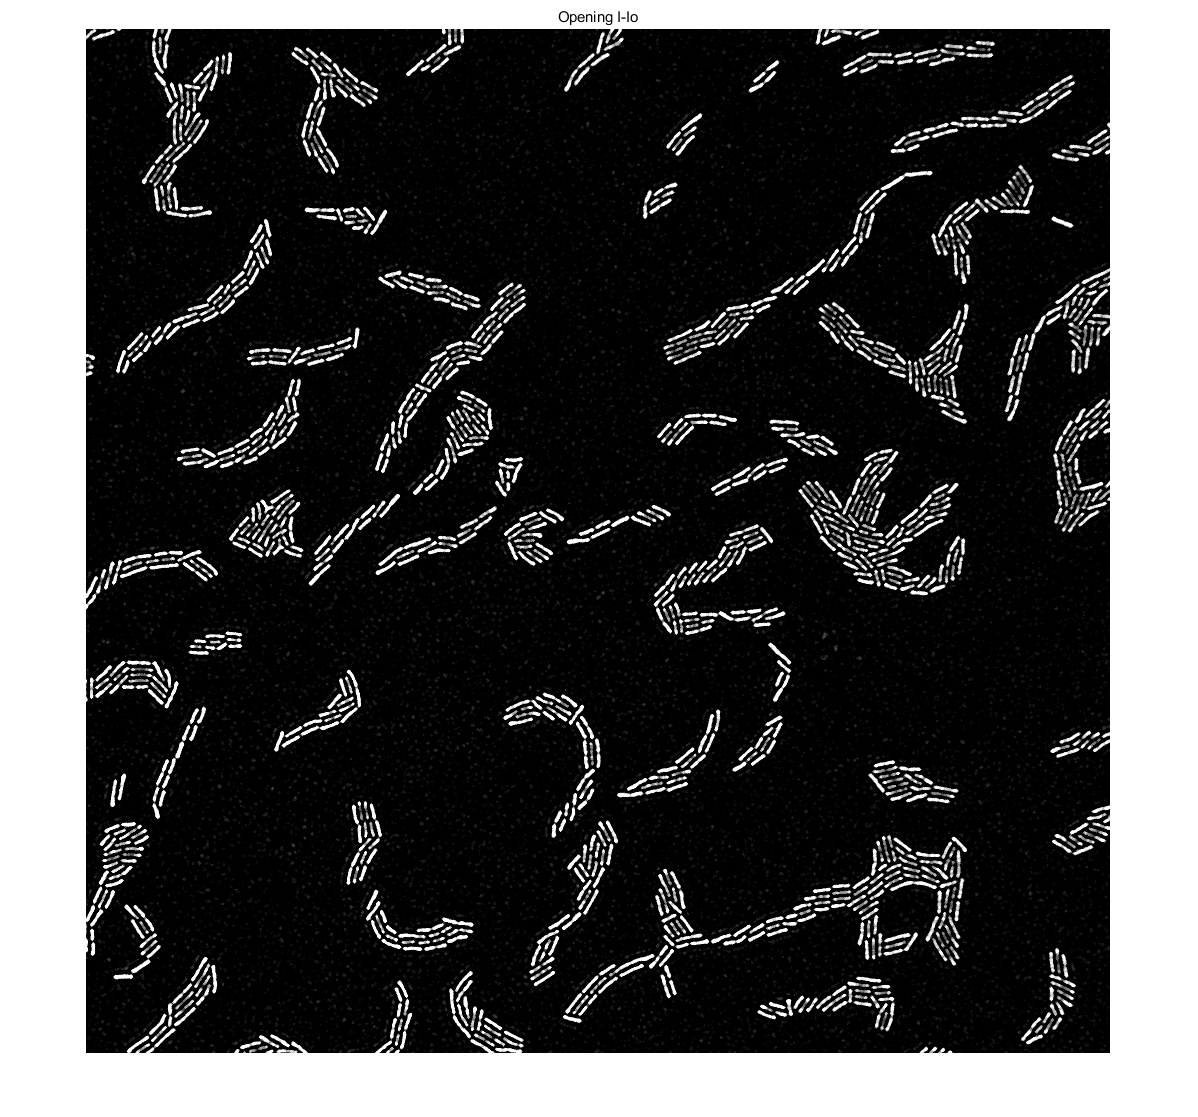

imshow(Io),title('Opening I-Io')

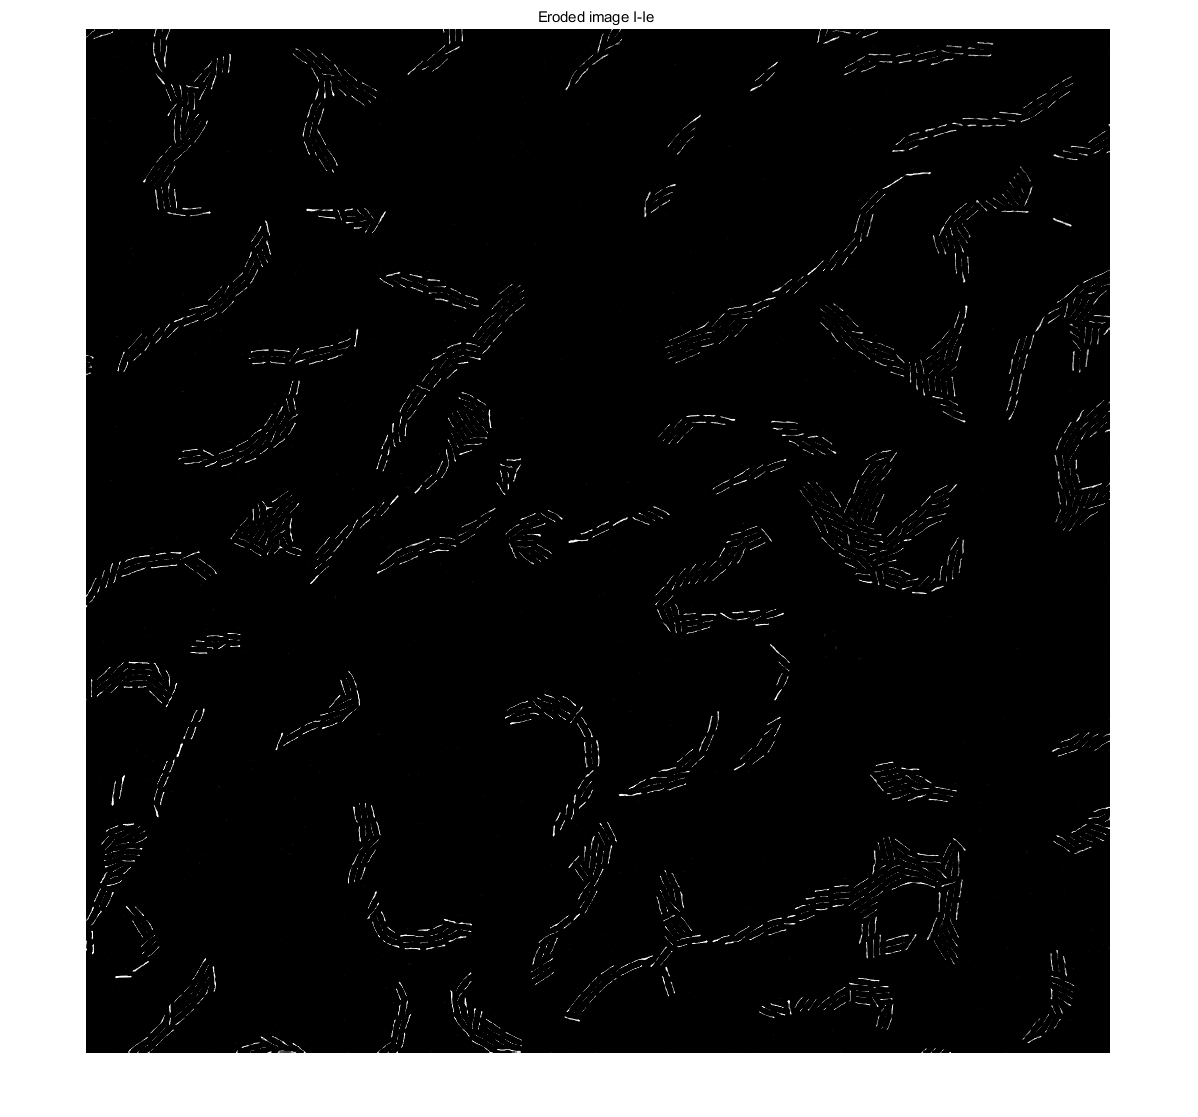


Ie = imerode(Io,strel('disk',3));
imshow(Ie), title('Eroded image I-Ie ')

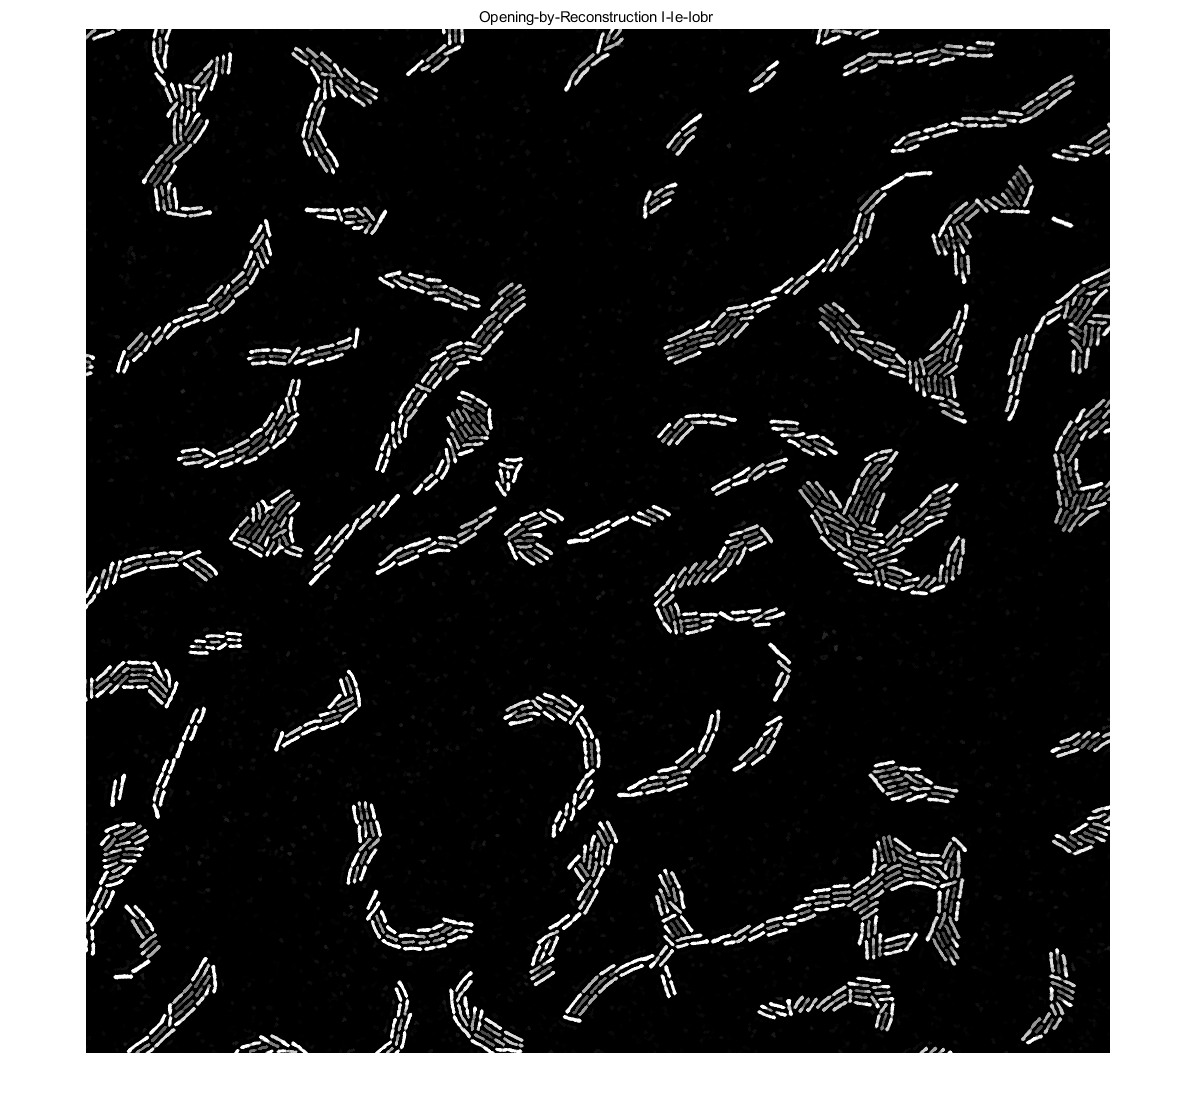

Iobr = imreconstruct(Ie,Io);
imshow(Iobr),title('Opening-by-Reconstruction I-Ie-Iobr ')

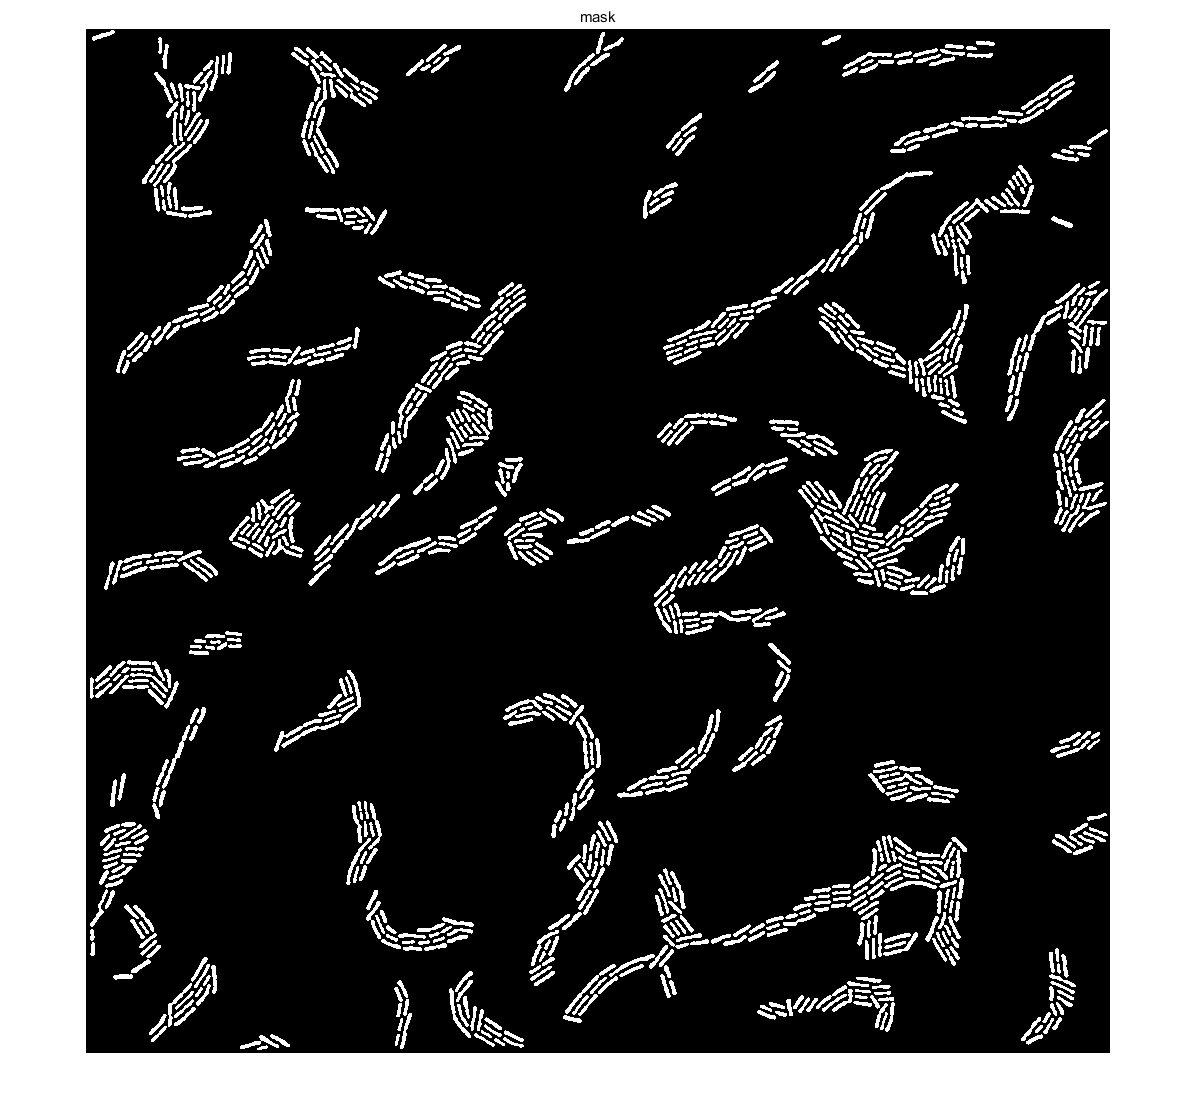


[bw,~] = myImageProcessing_cBFys(Iobr,'w');
% parameter
% % grayThresh=40;
% % areaThreshold=100;  % proper 60, overlap 60+40
% % maxIntensity=45;
imshow(bw),title('mask')

selectedBigRegions

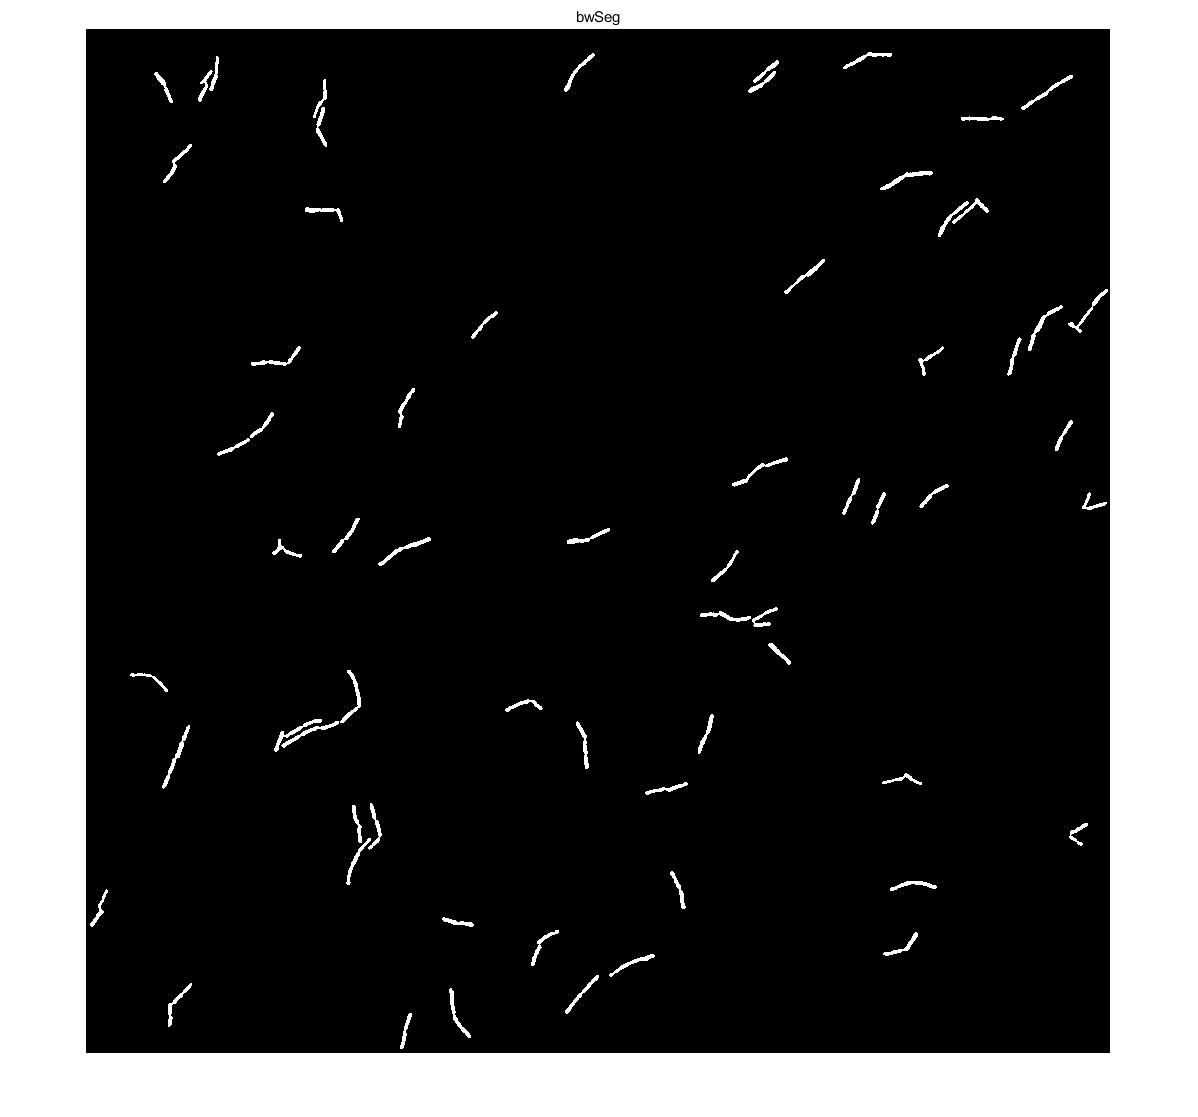

bwSeg = false(size(bw));

stats = regionprops(bw,'PixelIdxList');
pixelNum = zeros(2,numel(stats));
for j=1:numel(stats)
    pixelNum(1,j)=j;
    pixelNum(2,j)=numel(stats(j).PixelIdxList);
end
templogic=(pixelNum(2,:)>=500);
if sum(templogic)>0
    stats=stats(templogic);
    for k=1:numel(stats)
        bwSeg(stats(k).PixelIdxList)=true;
        bw(stats(k).PixelIdxList)=false;
    end
end

% 图像腐蚀进行分割 然后通过骨架处理 进行重建细菌

imshow (bwSeg),title ('bwSeg')

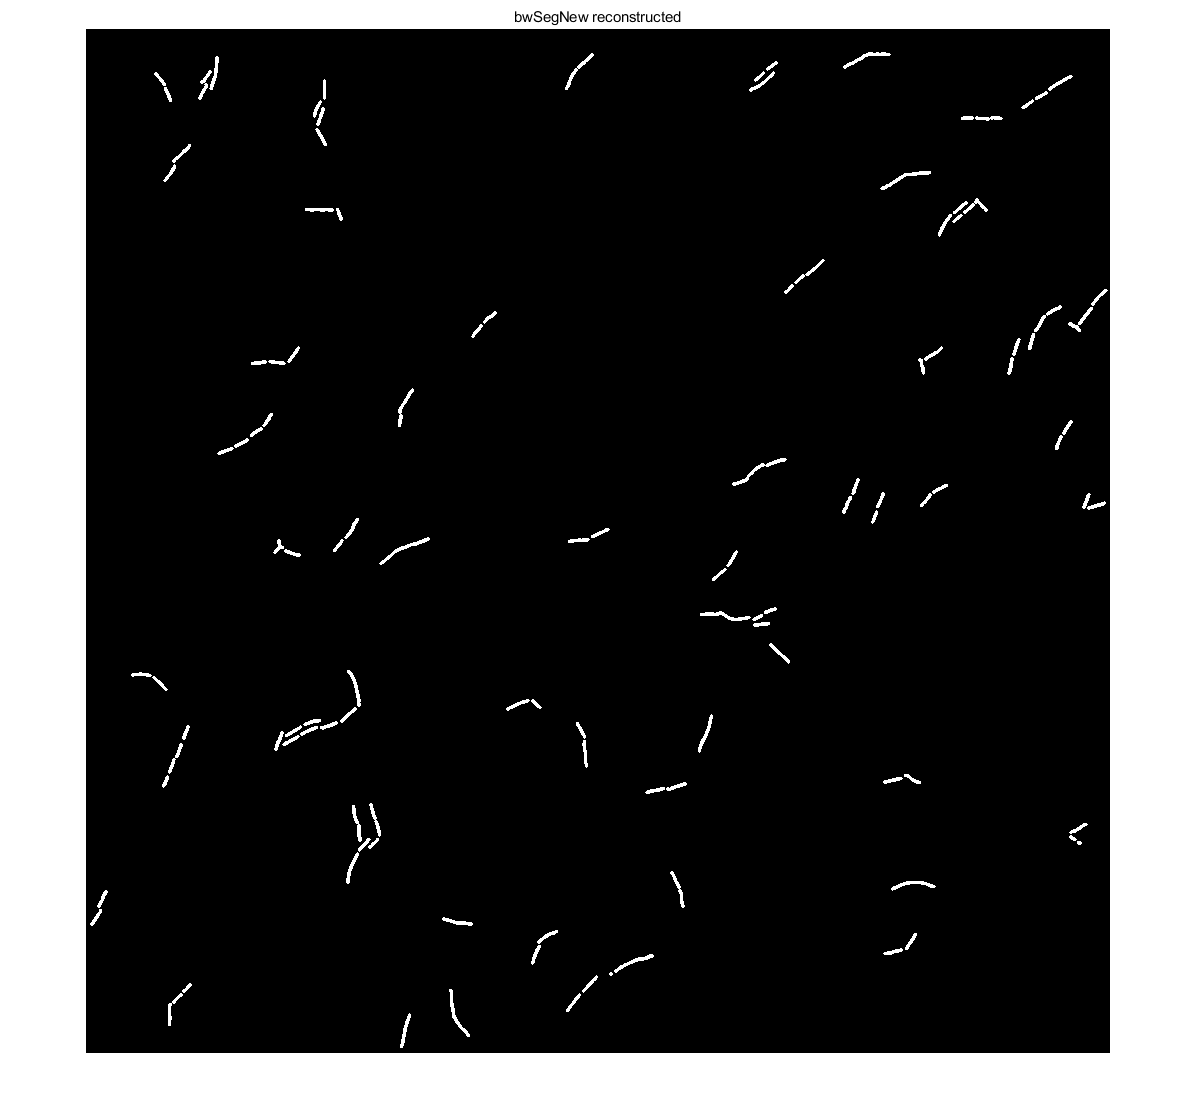

bwSeg1=imerode(bwSeg,ones(4));
bwSeg1 = bwareaopen(bwSeg1, 2);
skel = bwmorph(bwSeg1,'skel',Inf);
E = bwmorph(skel, 'endpoints');
skel=skel&(~E); %删除endpoint 要不膨胀会连在一起
E = bwmorph(skel, 'endpoints');
skel=skel&(~E); %删除两次
%重组细菌
se = strel('disk',4);
bwSegNew=imdilate(skel,se);
imshow(bwSegNew),title('bwSegNew reconstructed')

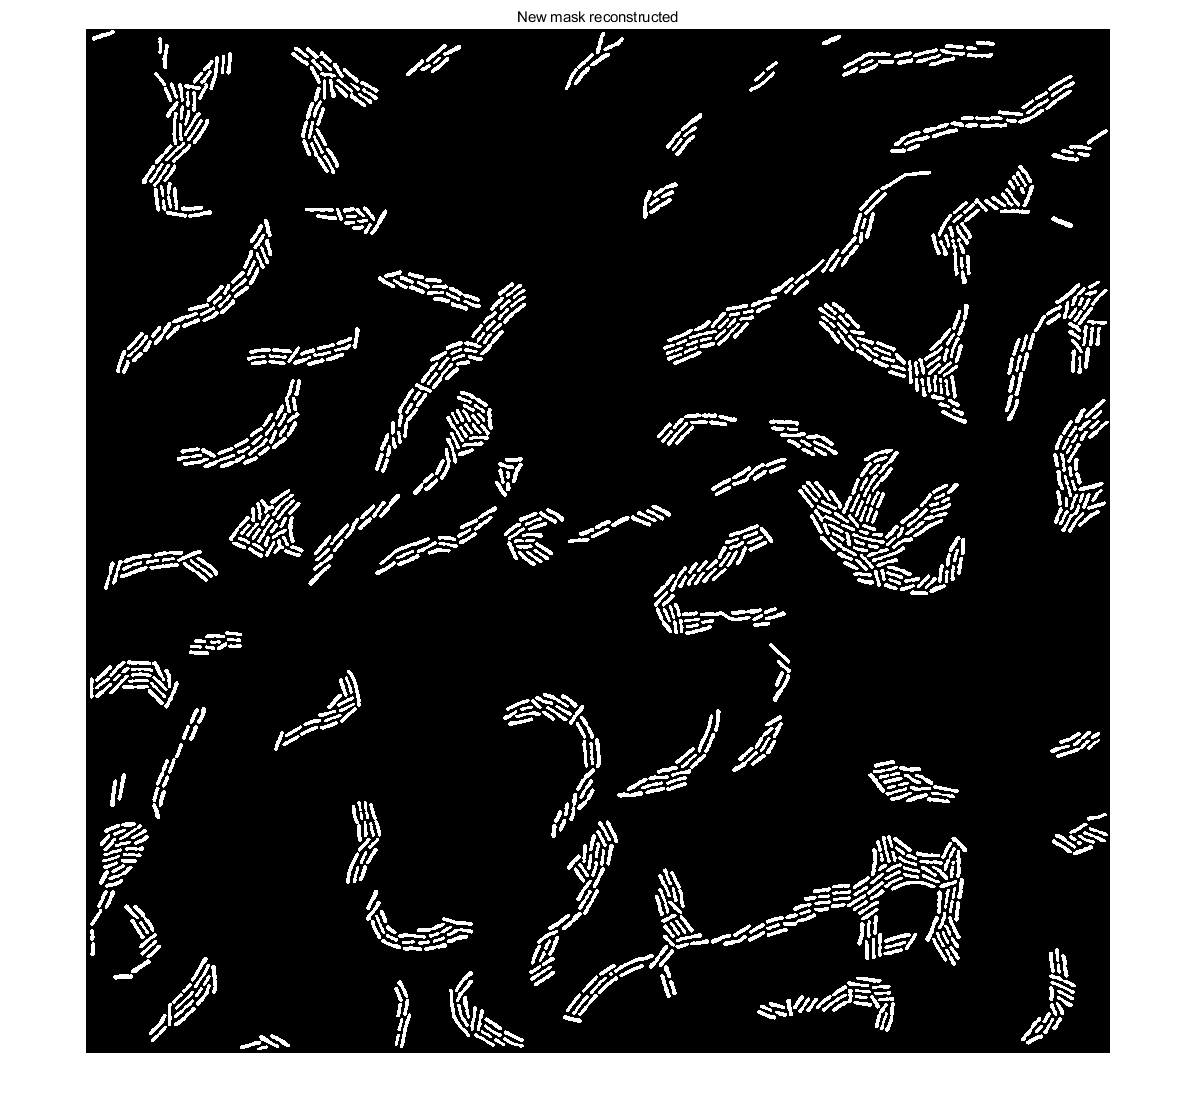


maskNew=bw|bwSegNew;
imshow(maskNew),title('New mask reconstructed')